f = @(x) x.*(0 <=x & x<3) + x.^2.*(3<=x & x<5)

f = function_handle with value:
    @(x)x.*(0<=x&x<3)+x.^2.*(3<=x&x<5)


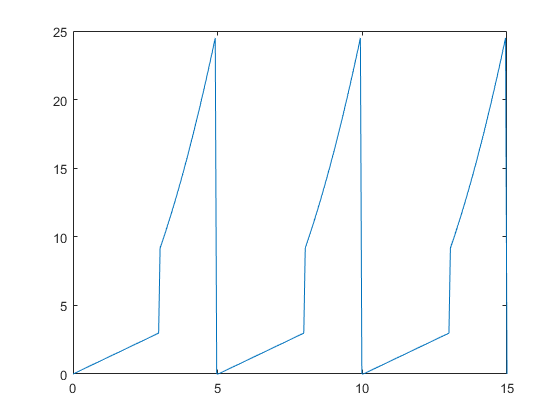

x = linspace(0, 5, 100);
y = f(x);
t = 3;
ry = repmat(y, 1, t);
rx = linspace(0, t*5, length(ry));
plot(rx, ry);

x = 3

x = 3

f = @(x) mod(x,5).*(0 <=mod(x, 5) & mod(x, 5)<3) + mod(x,5).^2.*(3<=mod(x,5) & mod(x,5)<5)

f = function_handle with value:
    @(x)mod(x,5).*(0<=mod(x,5)&mod(x,5)<3)+mod(x,5).^2.*(3<=mod(x,5)&mod(x,5)<5)


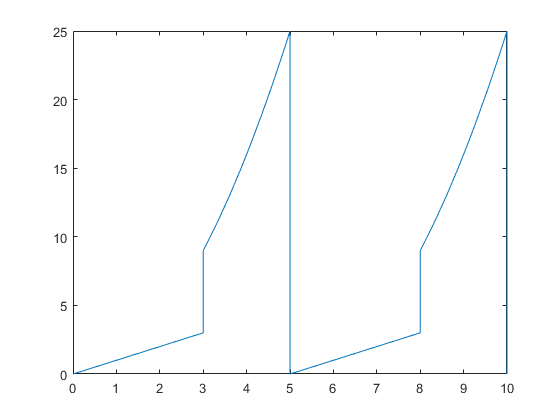

fplot(f, [0, 10])

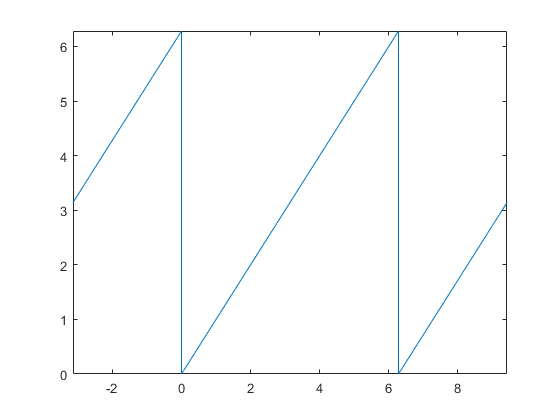

%%f = @(x) (pi-mod(x,2*pi)).*(-pi <=mod(x, 2*pi) & mod(x, 2*pi)<0) + mod(x,2*pi).*(0<=mod(x,2*pi) & mod(x,2*pi)<pi)
%%fplot(f, [-pi, 3*pi])

g = @(x) mod(x, 2*pi);
f = @(x) (pi-g(x)).*(-pi <= g(x) <0) + g(x).*(0<=g(x)<pi);
fplot(f, [-pi 3*pi])